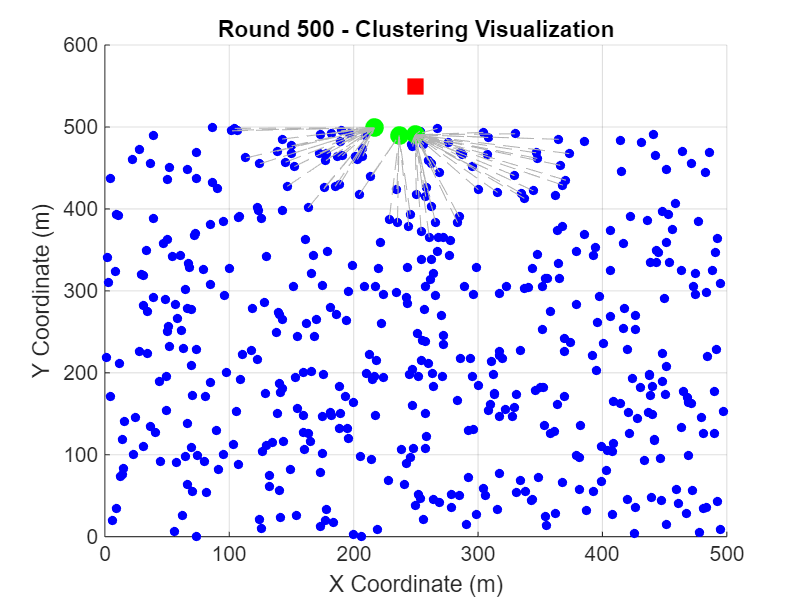

clc;
clear;
close all;

%% Parameters
numNodes = 500;               % Total number of sensor nodes
fieldDim = [500, 500];        % Field dimensions (meters)
baseStation = [250, 550];     % Base Station location
initialEnergy = 0.5;          % Initial energy of each node (Joules)
packetSize = 4000;            % Packet size (bits)
controlPacketSize = 200;      % Control packet size (bits)
energyPerBit = 50e-9;         % Energy dissipated per bit
ampEnergyFS = 10e-12;         % Energy for free space model
ampEnergyMP = 0.0013e-12;     % Energy for multipath model
thresholdDistance = 87;       % Distance threshold for FS/MP
alpha = 0.6;                  % Energy weight in CH selection
beta = 0.3;                   % Distance weight in CH selection
gamma = 0.1;                  % Random factor weight for CH selection
maxRounds = 500;              % Maximum simulation rounds
p = 0.05;                     % Percentage of nodes as CHs

%% Node Deployment
nodes = rand(numNodes, 2) .* fieldDim; % Random node deployment
energy = ones(numNodes, 1) * initialEnergy; % Initial energy

% Tracking variables
averageEnergy = zeros(maxRounds, 1);
aliveNodesCount = zeros(maxRounds, 1);

% For visualization and comparison
clusterHistory = cell(maxRounds, 1);
CHHistory = cell(maxRounds, 1);

%% Simulation Loop
figure; % Set up a visualization figure
for round = 1:maxRounds
    aliveNodes = find(energy > 0);
    aliveNodesCount(round) = length(aliveNodes);

    if isempty(aliveNodes)
        disp('All nodes are dead.');
        break;
    end

    % Update average energy
    averageEnergy(round) = mean(energy(aliveNodes));

    %% Multi-Criteria CH Selection
    distToBS = vecnorm(nodes(aliveNodes, :) - baseStation, 2, 2);
    scores = alpha * (energy(aliveNodes) / max(energy(aliveNodes))) - ...
             beta * (distToBS / max(distToBS)) + ...
             gamma * rand(size(aliveNodes)); % Random factor
    [~, sortedIdx] = sort(scores, 'descend');
    numCH = max(1, floor(length(aliveNodes) * p)); % CH count
    CHIdx = aliveNodes(sortedIdx(1:numCH)); % Cluster Heads
    CHHistory{round} = CHIdx;

    %% Cluster Formation
    clusterAssignments = zeros(numNodes, 1);
    for i = 1:numNodes
        if ismember(i, CHIdx)
            clusterAssignments(i) = i;
        else
            [~, nearestCH] = min(vecnorm(nodes(i, :) - nodes(CHIdx, :), 2, 2));
            clusterAssignments(i) = CHIdx(nearestCH);
        end
    end
    clusterHistory{round} = clusterAssignments;

    %% Energy Dissipation
    for i = 1:numNodes
        if energy(i) <= 0, continue; end
        if ismember(i, CHIdx) % CH to base station
            distance = norm(nodes(i, :) - baseStation);
            if distance < thresholdDistance
                energy(i) = energy(i) - (packetSize * energyPerBit + packetSize * ampEnergyFS * distance^2);
            else
                energy(i) = energy(i) - (packetSize * energyPerBit + packetSize * ampEnergyMP * distance^4);
            end
        else % Node to CH
            assignedCH = clusterAssignments(i);
            distance = norm(nodes(i, :) - nodes(assignedCH, :));
            if distance < thresholdDistance
                energy(i) = energy(i) - (packetSize * energyPerBit + packetSize * ampEnergyFS * distance^2);
            else
                energy(i) = energy(i) - (packetSize * energyPerBit + packetSize * ampEnergyMP * distance^4);
            end
        end
    end

    %% Visualization of Clustering
    clf; % Clear the current figure
    hold on;
    scatter(nodes(:, 1), nodes(:, 2), 20, 'b', 'filled'); % Sensor nodes
    scatter(baseStation(1), baseStation(2), 100, 'r', 'filled', 's'); % Base station
    scatter(nodes(CHIdx, 1), nodes(CHIdx, 2), 80, 'g', 'filled'); % CHs

    % Draw connections
    for i = 1:numNodes
        if energy(i) > 0 && clusterAssignments(i) ~= i
            line([nodes(i, 1), nodes(clusterAssignments(i), 1)], ...
                 [nodes(i, 2), nodes(clusterAssignments(i), 2)], ...
                 'Color', [0.7, 0.7, 0.7], 'LineStyle', '--');
        end
    end

    % Title and axes
    title(['Round ', num2str(round), ' - Clustering Visualization']);
    xlabel('X Coordinate (m)');
    ylabel('Y Coordinate (m)');
    axis([0 fieldDim(1) 0 fieldDim(2) + 100]);
    grid on;
    drawnow;
end


disp(['Simulation completed after ', num2str(round), ' rounds.']);

Simulation completed after 500 rounds.


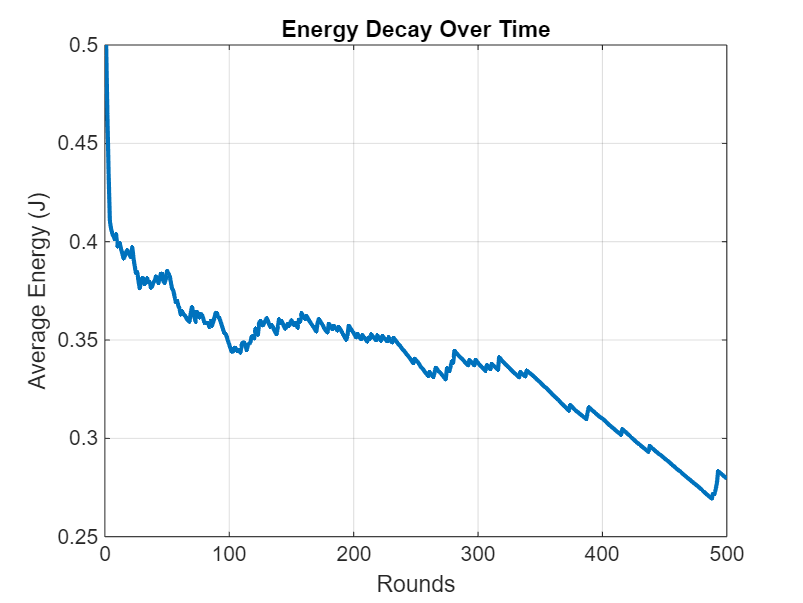


%% 1. Energy Decay Over Time
figure;
plot(1:round, averageEnergy(1:round), 'LineWidth', 2);
title('Energy Decay Over Time');
xlabel('Rounds');
ylabel('Average Energy (J)');
grid on;

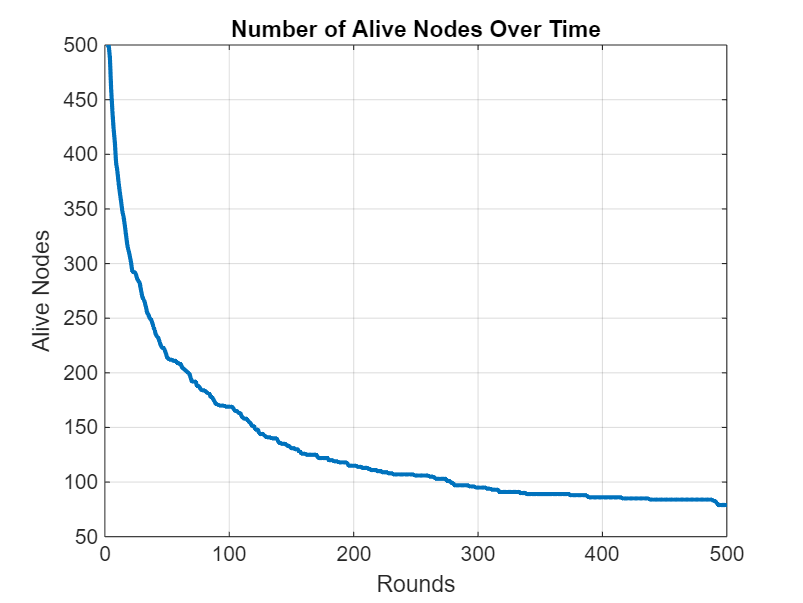


%% 2. Comparison of Alive Nodes Over Time
figure;
plot(1:round, aliveNodesCount(1:round), 'LineWidth', 2);
title('Number of Alive Nodes Over Time');
xlabel('Rounds');
ylabel('Alive Nodes');
grid on;

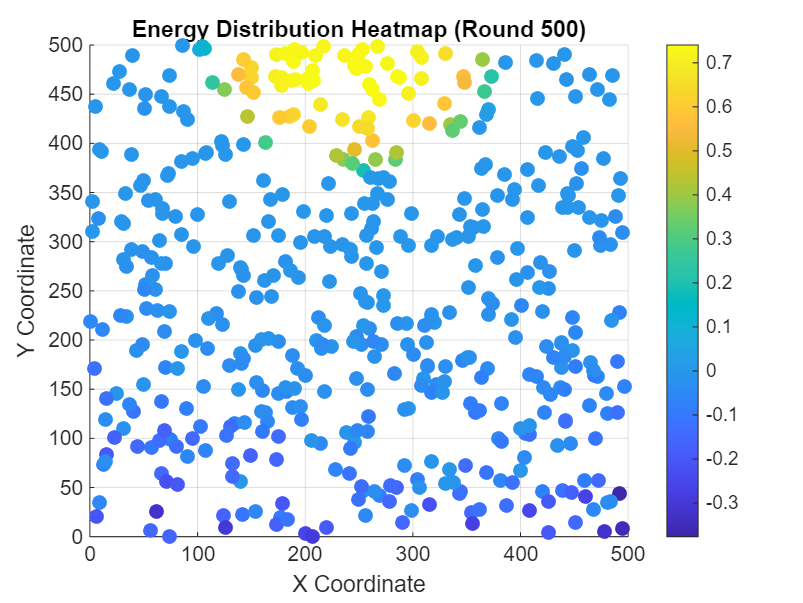


%% 3. Energy Distribution Heatmap
figure;
normalizedEnergy = energy / initialEnergy; % Normalize energy for visualization
scatter(nodes(:, 1), nodes(:, 2), 50, normalizedEnergy, 'filled');
colorbar;
title(['Energy Distribution Heatmap (Round ', num2str(round), ')']);
xlabel('X Coordinate');
ylabel('Y Coordinate');
grid on;

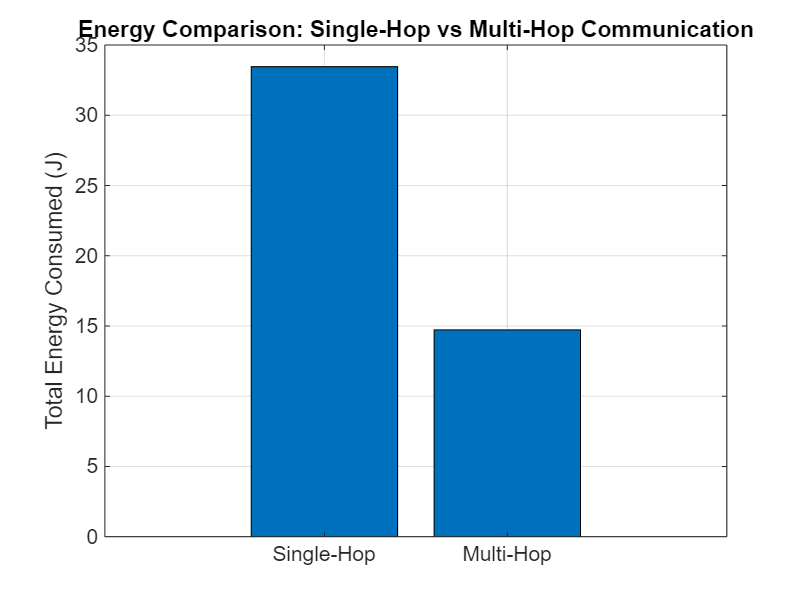


%% 4. Energy Comparison: Single-Hop vs Multi-Hop
singleHopEnergy = zeros(maxRounds, 1);
multiHopEnergy = zeros(maxRounds, 1);
for r = 1:round
    for i = 1:numNodes
        if energy(i) > 0
            assignedCH = clusterHistory{r}(i);
            distanceToBase = norm(nodes(i, :) - baseStation);
            distanceToCH = norm(nodes(i, :) - nodes(assignedCH, :));
            singleHopEnergy(r) = singleHopEnergy(r) + packetSize * (energyPerBit + ampEnergyFS * distanceToBase^2);
            multiHopEnergy(r) = multiHopEnergy(r) + packetSize * (energyPerBit + ampEnergyFS * distanceToCH^2);
        end
    end
end

% Bar chart comparison
figure;
bar([sum(singleHopEnergy), sum(multiHopEnergy)]);
xticklabels({'Single-Hop', 'Multi-Hop'});
ylabel('Total Energy Consumed (J)');
title('Energy Comparison: Single-Hop vs Multi-Hop Communication');
grid on;